%% 角加速度外乱
syms t real
syms g a
disp('tan==============')

tan==============


th = a*t^2/2;
d2x = g*tan(th)

$$d2x = g\,\tan\left(\frac{a\,t^{2}}{2}\right)$$

d3x = simplify(diff(d2x,t))

$$d3x = a\,g\,t\,\left({\tan\left(\frac{a\,t^{2}}{2}\right)}^{2}+1\right)$$

d4x = simplify(diff(d3x,t))

$$d4x = a\,g\,\left({\tan\left(\frac{a\,t^{2}}{2}\right)}^{2}+1\right)\,\left(2\,a\,t^{2}\,\tan\left(\frac{a\,t^{2}}{2}\right)+1\right)$$

d2z = -(g - g*cos(th))

$$d2z = g\,\cos\left(\frac{a\,t^{2}}{2}\right)-g$$

disp('sin==============')

sin==============


d2x = g*sin(th)

$$d2x = g\,\sin\left(\frac{a\,t^{2}}{2}\right)$$

d3x = simplify(diff(d2x,t))

$$d3x = a\,g\,t\,\cos\left(\frac{a\,t^{2}}{2}\right)$$

d4x = simplify(diff(d3x,t))

$$d4x = a\,g\,\left(\cos\left(\frac{a\,t^{2}}{2}\right)-a\,t^{2}\,\sin\left(\frac{a\,t^{2}}{2}\right)\right)$$

d2z = -(g - g*cos(th))

$$d2z = g\,\cos\left(\frac{a\,t^{2}}{2}\right)-g$$

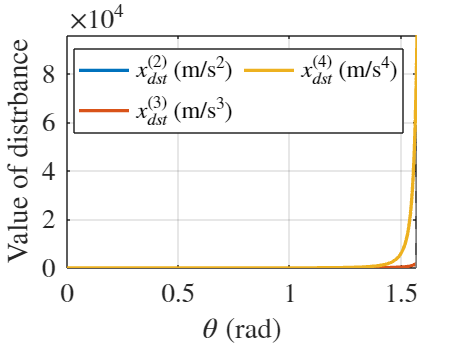


g = 9.81;
a = 1.2;
% w = 1.5;
%tan
th = a*t^2/2;
d2x = g*tan(th);
d3x = simplify(diff(d2x,t));
d4x = simplify(diff(d3x,t));
d2z = -(g - g*cos(th));

i=1;
figure(i)
LineWidth=2;
labelx='$\theta$ (rad)';
labely='Value of distrbance';
legendLabels=["$x_{dst}^{(2)}$ $(\rm{m/s^2})$","$x_{dst}^{(3)}$ $(\rm{m/s^3})$","$x_{dst}^{(4)}$ $(\rm{m/s^4})$"];
legendColumns=2;
fontSize=16;

fplot(d2x,[0,pi/2], 'LineWidth', LineWidth)
hold on
fplot(d3x,[0,pi/2], 'LineWidth', LineWidth)
fplot(d4x,[0,pi/2], 'LineWidth', LineWidth)
xlabel(labelx,'Interpreter','latex')
ylabel(labely,'Interpreter','latex')
legend(legendLabels,'NumColumns',legendColumns,'Interpreter','latex')
% title(titleName)
set(gca,'FontSize',fontSize,"TickLabelInterpreter","latex")
grid on
hold off

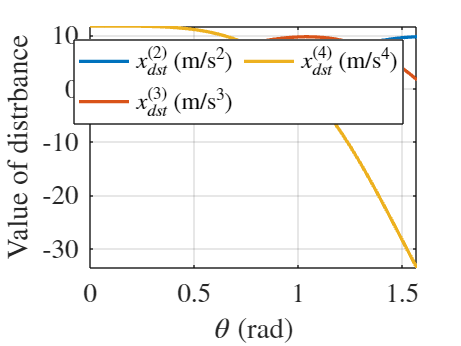

i=i+1;

%sin
d2x = g*sin(th);
d3x = simplify(diff(d2x,t));
d4x = simplify(diff(d3x,t));
% d2z = -(g - g*cos(th))

figure(i)
LineWidth=2;
labelx='$\theta$ (rad)';
labely='Value of distrbance';
legendLabels=["$x_{dst}^{(2)}$ $(\rm{m/s^2})$","$x_{dst}^{(3)}$ $(\rm{m/s^3})$","$x_{dst}^{(4)}$ $(\rm{m/s^4})$"];
legendColumns=2;
fontSize=16;

fplot(d2x,[0,pi/2], 'LineWidth', LineWidth)
hold on
fplot(d3x,[0,pi/2], 'LineWidth', LineWidth)
fplot(d4x,[0,pi/2], 'LineWidth', LineWidth)
xlabel(labelx,'Interpreter','latex')
ylabel(labely,'Interpreter','latex')
legend(legendLabels,'NumColumns',legendColumns,'Interpreter','latex')
% title(titleName)
set(gca,'FontSize',fontSize,"TickLabelInterpreter","latex")
grid on
hold off

i=i+1;


%sin 角速度外乱
% th = w*t;
% d2x = g*sin(th)
% d3x = simplify(diff(d2x,t))
% d4x = simplify(diff(d3x,t))
% d2z = -(g - g*cos(th))
% 
% figure(i)
% fplot(d2x,[0,pi/2])
% hold on
% fplot(d3x,[0,pi/2])
% fplot(d4x,[0,pi/2])
% fplot(d2z,[0,pi/2])
% hold off
% legend("d2x","d3x","d4x","d2z")
% i=i+1;